# Sampled Feedback System for Franka Emika Panda

Add Path

clear;clc;
close all
addpath("PandaDyn\")
addpath("Dynamics\")
addpath("..\ReadYAML\")
config=ReadYaml("Configuration\FrankaEmikaPanda.yaml");

The system follows


$$M\left(\vec{q}\right) \ddot{\vec{q}} + C \left( \vec{q}, \dot{\vec{q}} \right) \dot{\vec{q}} + G \left( \vec{q} \right) = - K_{p} \left( \hat{q} - \vec{q}_{d} \right) - K_{d} \dot{\hat{q}} - f \left( \dot{\vec{q}} \right),$$


where friction follows


$$f^{j} (\dot{q})= \frac{\varphi_{1,j}}{1 + e^{- \varphi_{2,j} \left( \dot{q}_{j} + \varphi_{3,j} \right)}} - \frac{\varphi_{1,j}}{1 + e^{- \varphi_{2,j} \varphi_{3,j}}}.$$


## Configurations

Sampling Time, Time Step & Simulation Time

Critical $t_s$ is $0.00789$ second.

dt=config.dt;
% ts=config.ts;
ts=0.008;
SimulationTime=config.SimulationTime;
% SimulationTime=3;
TimeSpan=0:dt:SimulationTime;

Initial Condition

TargetAngle=config.TargetAngle';
StateInitial=config.StateInitial';

Gains

Kp=diag(config.Kp);
Kd=diag(config.Kd);

Time History Matrix

StateTimeHistoryDigital=zeros(7*2,round(SimulationTime/dt)+1);
SampledStateTimeHistoryDigital=zeros(7*2,floor(SimulationTime/ts));
TorqueTimeHistoryDigital=zeros(7,round(SimulationTime/dt)+1);
StateTimeHistoryDigital(:,1)=StateInitial;
SampledStateTimeHistoryDigital(:,1)=StateInitial;
TorqueTimeHistoryDigital(:,1)=PDTorque(Kp,Kd,SampledStateTimeHistoryDigital(:,1),TargetAngle);

Solver Option

option=odeset('RelTol', config.ODE_RelTol, ...
    'AbsTol', config.ODE_AbsTol);

For $t\in[0,t_s]$, torque $\tau$ is computed with state at $t=0$, the $1$st column of StateTimeHistoryDigital.

For $t\in[t_s,2t_s]$, torque $\tau$ is computed with state at $t=0$, the $1$st column of StateTimeHistoryDigital.

For $t\in[2t_s,3t_s]$, torque $\tau$ is computed with state at $t=t_s$, the $2$nd column of StateTimeHistoryDigital.


$$\vdots$$


For $t\in[k t_s,(k+1)t_s]$, torque $\tau$ is computed with state at $t=(k-1)t_s$, the $k$th column of StateTimeHistoryDigital.

## Digital Feedback Control Case

Simulation

tic
bar=waitbar(0,"Start Simulation");
for i=1:floor(SimulationTime/ts)
    SampledStateTimeHistoryDigital(:,i)=StateTimeHistoryDigital(:,(i-1)*round(ts/dt)+1);
    if i==1
        Tau=PDTorque(Kp,Kd,SampledStateTimeHistoryDigital(:,1),TargetAngle);
    else
        Tau=PDTorque(Kp,Kd,SampledStateTimeHistoryDigital(:,i-1),TargetAngle);
    end
    TorqueTimeHistoryDigital(:,(i-1)*round(ts/dt)+2:i*round(ts/dt)+1)=repmat(Tau,1,round(ts/dt));
    [t,State]=ode45(@(t,State)ODE(t,State,Tau),TimeSpan((i-1)*round(ts/dt)+1:i*round(ts/dt)+1), ...
        StateTimeHistoryDigital(:,(i-1)*round(ts/dt)+1),option);
    StateTimeHistoryDigital(:,(i-1)*round(ts/dt)+2:i*round(ts/dt)+1)=State(2:end,:)';
    str=[num2str(100*i/floor(SimulationTime/ts)),'%',' Finished'];
    waitbar(i/floor(SimulationTime/ts),bar,str);
end
waitbar(1,bar,"Handling Final Interval");
if floor(SimulationTime/ts)~=ceil(SimulationTime/ts)
    [t,State]=ode45(@(t,State)ODE(t,State,Tau),TimeSpan(floor(SimulationTime/ts)*round(ts/dt)+1:end), ...
        StateTimeHistoryDigital(:,floor(SimulationTime/ts)*round(ts/dt)+1),option);
    StateTimeHistoryDigital(:,floor(SimulationTime/ts)*round(ts/dt)+2:end)=State(2:end,:)';
    TorqueTimeHistoryDigital(:,floor(SimulationTime/ts)*round(ts/dt)+2:end)=repmat(Tau,1, ...
        round(mod(SimulationTime,ts)/dt));
end
delete(bar);
toc

历时 68.127694 秒。


## Visualization for Digital Feedback Control

Collect Data for Visualization

eTimeHistoryDigital=StateTimeHistoryDigital(1:7,:)-TargetAngle;

$e-t$ Diagram

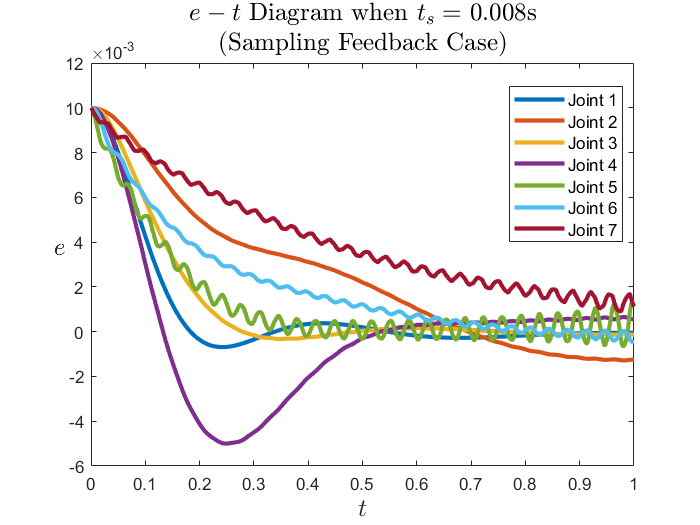

plot(TimeSpan,eTimeHistoryDigital,"LineWidth",2.5)
title(["$$e-t$$ Diagram when $$t_s=$$ "+num2str(ts)+"s","(Sampling Feedback Case)"], ...
    "FontSize",15,"Interpreter","latex")
xlabel("$$t$$","FontSize",15,"Interpreter","latex")
ylabel("$$e$$","FontSize",15,"Rotation",pi/2,"Interpreter","latex")
legend("Joint 1","Joint 2","Joint 3","Joint 4","Joint 5","Joint 6","Joint 7","Fontsize",10,"Location","best")

$\dot{e}-t$ Diagram

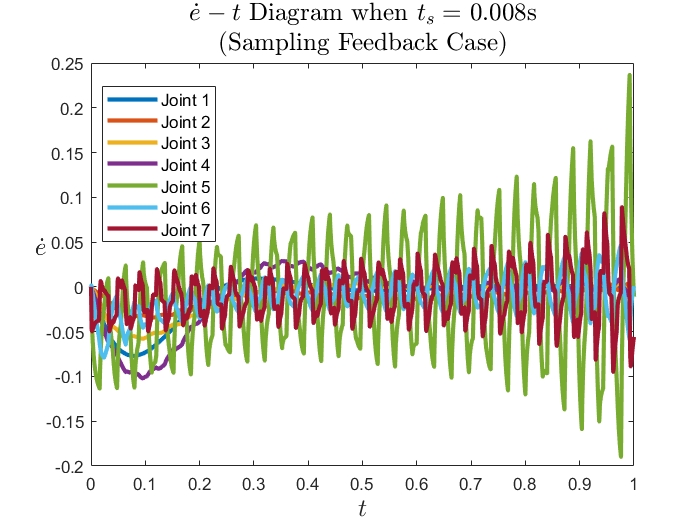

plot(TimeSpan,StateTimeHistoryDigital(8:14,:),"LineWidth",2.5)
title(["$$ \dot{e}-t $$ Diagram when $$t_s=$$ "+num2str(ts)+"s","(Sampling Feedback Case)"], ...
    "FontSize",15,"Interpreter","latex")
xlabel("$$t$$","FontSize",15,"Interpreter","latex")
ylabel("$$\dot{e}$$","FontSize",15,"Rotation",pi/2,"Interpreter","latex")
legend("Joint 1","Joint 2","Joint 3","Joint 4","Joint 5","Joint 6","Joint 7","Fontsize",10,"Location","best")

$\tau-t$ Diagram

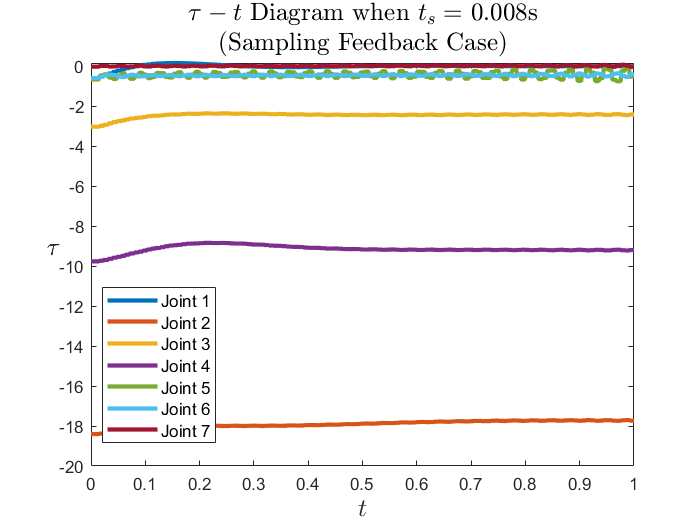

plot(TimeSpan,TorqueTimeHistoryDigital,"LineWidth",2.5)
title(["$$ \tau-t $$ Diagram when $$t_s=$$ "+num2str(ts)+"s","(Sampling Feedback Case)"], ...
    "FontSize",15,"Interpreter","latex")
xlabel("$$t$$","FontSize",15,"Interpreter","latex")
ylabel("$$\tau$$","FontSize",15,"Rotation",pi/2,"Interpreter","latex")
legend("Joint 1","Joint 2","Joint 3","Joint 4","Joint 5","Joint 6","Joint 7","Fontsize",10,"Location","best")

## Visualization in Cartesian Space

MDH parameter of Franka Emika Panda

mdl_panda

Trajectory of End Effector

EndEffectorLocDigital=panda.fkine(StateTimeHistoryDigital(1:7,:)').transl';

Target of End Effector

EndEffectorLocTarget=panda.fkine(TargetAngle).transl';

End Effector Trajectory

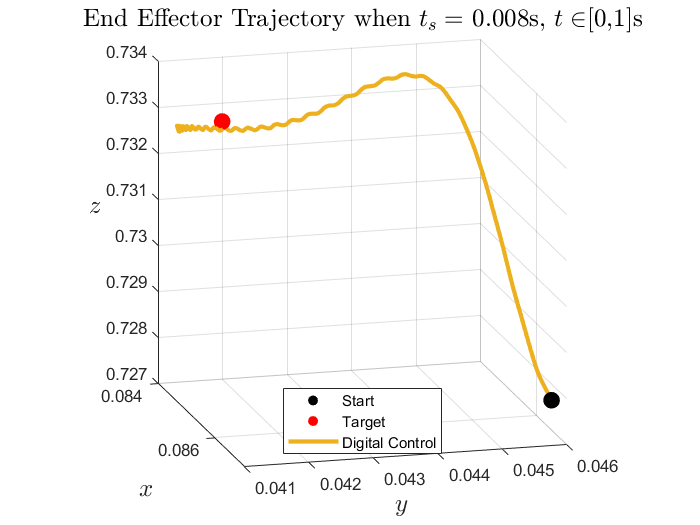

scatter3(EndEffectorLocDigital(1,1),EndEffectorLocDigital(2,1),EndEffectorLocDigital(3,1),100,"black","filled","o")
hold on
scatter3(EndEffectorLocTarget(1),EndEffectorLocTarget(2),EndEffectorLocTarget(3),100,"Red","filled","o")
plot3(EndEffectorLocDigital(1,:),EndEffectorLocDigital(2,:),EndEffectorLocDigital(3,:),"LineWidth",2.5)
hold off
title("End Effector Trajectory when $$t_s=$$ "+num2str(ts)+ ...
    "s, $$t \in$$[0,"+num2str(SimulationTime)+"]s", ...
    "FontSize",15,"Interpreter","latex")
view(75,15)
pbaspect([1 1 1])
legend("Start","Target","Digital Control","Location","south")
xlabel("$$x$$","Interpreter","latex","FontSize",15)
ylabel("$$y$$","Interpreter","latex","FontSize",15)
zlabel("$$z$$","Interpreter","latex","FontSize",15,"Rotation",pi/2)
grid on

## Save Data

save("Data\StateTimeHistory_Sampled_"+ ...
    datestr(datetime("today"),"yyyy_mm_dd")+".mat","StateTimeHistoryDigital")

Remove Path

rmpath("Dynamics\")
rmpath("PandaDyn\")
rmpath("..\ReadYAML\")

robot_col=loadrobot('frankaEmikaPanda','DataFormat',"column","Gravity",[0 0 -9.81]);

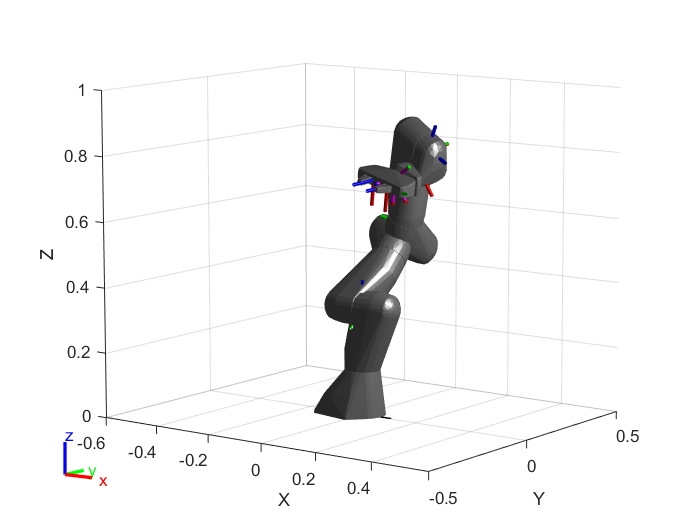

show(robot_col,[StateInitial(1:7);0.03;0.03]);
xlim([-0.6 0.6])
ylim([-0.5 0.5])
zlim([0 1])
view([36.41 9.24])